## **Matrix multiplication** 

Consider three matrices A,B,C of size mxn, nxp, pxl respectivesly, 

Although, the matrix multiplication 

A = rand(500,100);
B = rand(100,700);
C = rand(700,900);
disp('Matrix multiplication ABC')

Matrix multiplication ABC


t1= 0

t1 = 0

for i=1:50
tic
(A*B)*C;
t1 =t1 +toc;

t2 =0
tic
A*(B*C);
t2 = t2 + toc;
end

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

t2 = 0

disp(fprintf('Average time taken for (A*B)*C is %f', (t1/50)));

Average time taken for (A*B)*C is 0.039701    42



disp(fprintf('Average time taken for A*(B*C) is %f', t2/50));

Average time taken for A*(B*C) is 0.000092    42



## Low rank Algebra

- Matrix-Matrix multiplication 

- Matrix-Vector multiplication

- Addition of two low-rank matrices

- Compression of a low-rank matrix

## Singular Value Decomposition(SVD)

Given a matrix A(m x n) the Singular Value Decomposition of that matrix is given as A = USV'

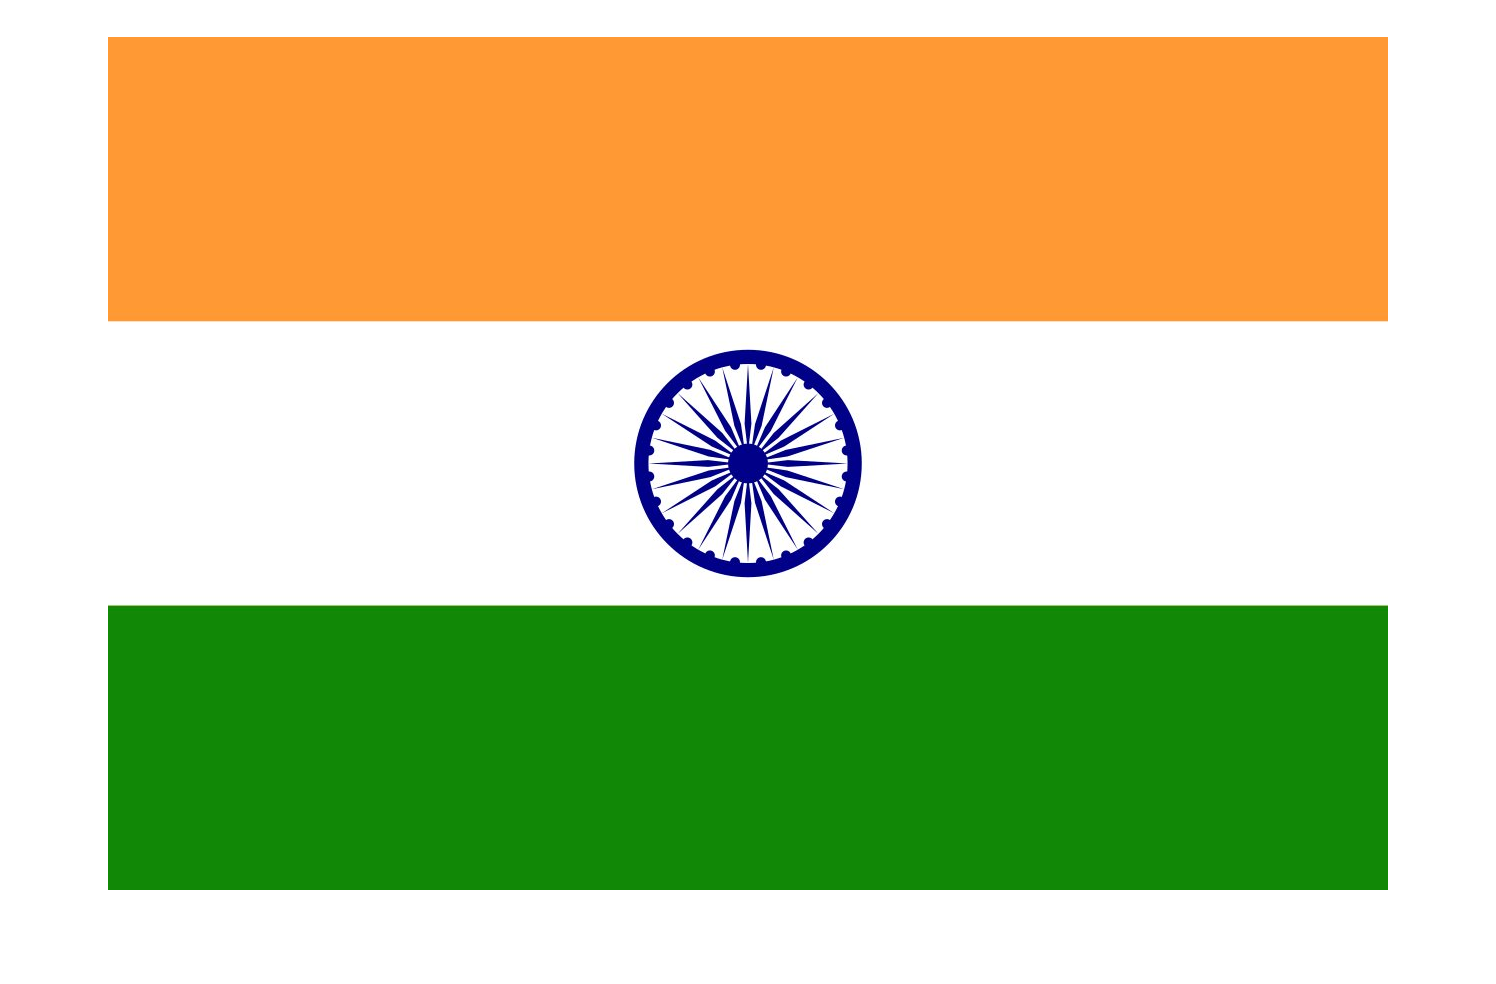

Italy = imread('india.jpg');
imshow(Italy)

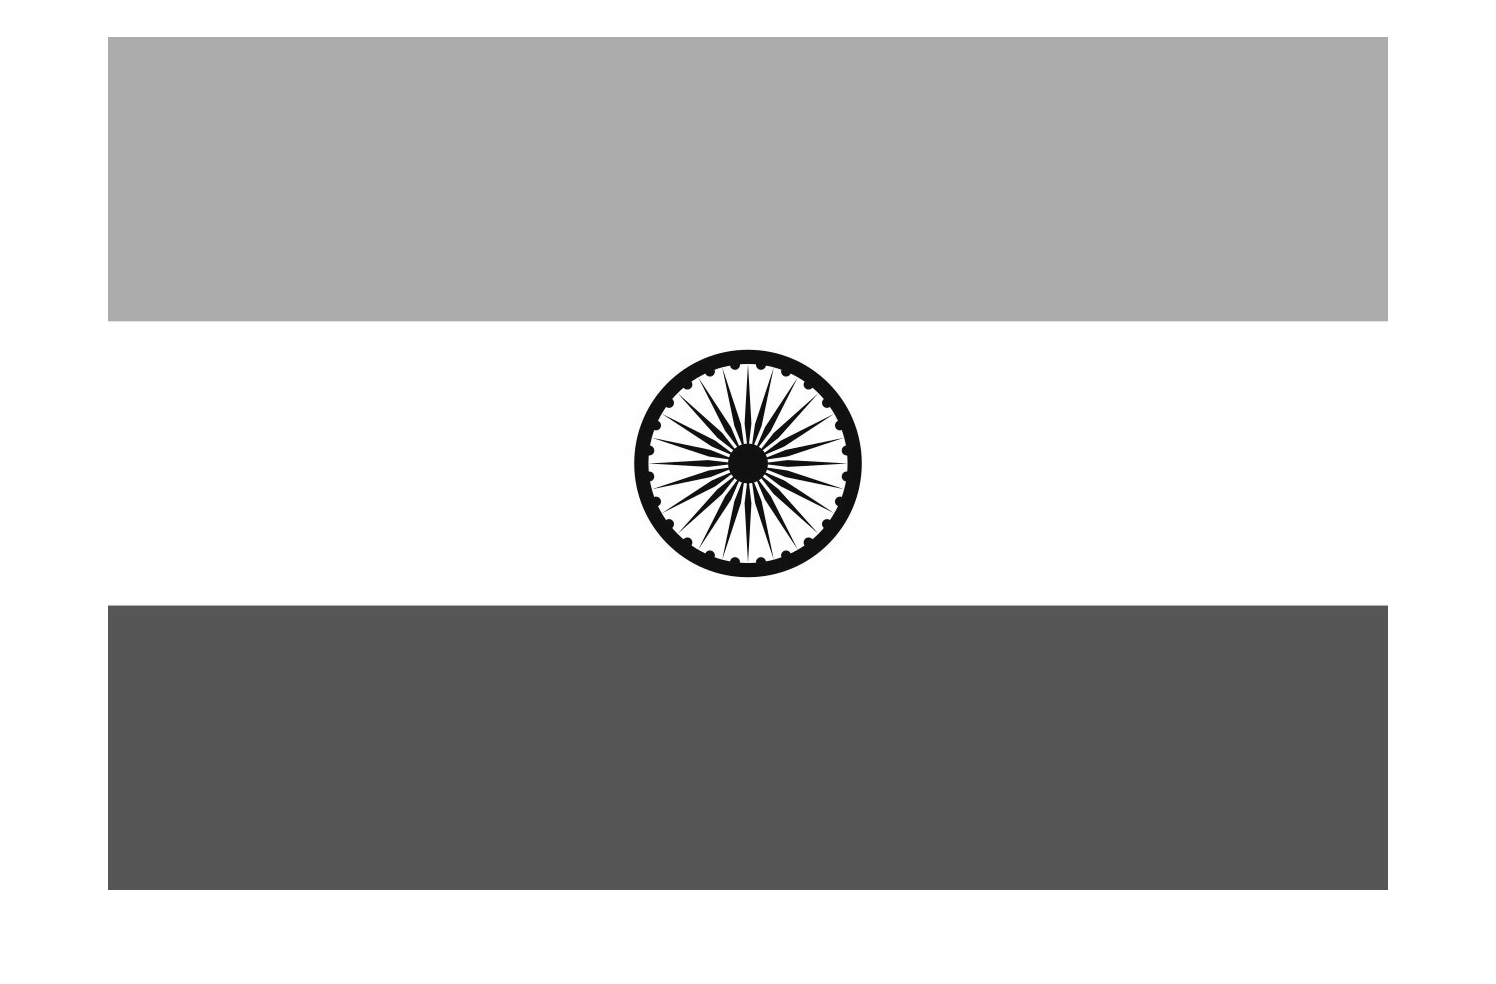

Italy = rgb2gray(Italy);
imshow(Italy)

rank(double(Italy))

ans = 244

[ui,si,vi] = svd(double(Italy),"econ")

ui =    -0.0328    0.0246   -0.0166    0.0033   -0.0009    0.0022   -0.0002    0.0028   -0.0032    0.0010   -0.0011    0.0016   -0.0001    0.0011   -0.0000    0.0025   -0.0024    0.0008   -0.0018    0.0025   -0.0001   -0.0006    0.0026   -0.0024    0.0046   -0.0004   -0.0006    0.0002    0.0002    0.0002   -0.0006   -0.0002   -0.0001   -0.0002    0.0008   -0.0019    0.0024   -0.0008    0.0009   -0.0003    0.0007   -0.0006    0.0002   -0.0001    0.0003   -0.0004    0.0005   -0.0018    0.0009   -0.0008
   -0.0328    0.0246   -0.0166    0.0033   -0.0009    0.0022   -0.0002    0.0028   -0.0032    0.0010   -0.0011    0.0016   -0.0001    0.0011   -0.0000    0.0025   -0.0024    0.0008   -0.0018    0.0025   -0.0001   -0.0006    0.0026   -0.0024    0.0046   -0.0004   -0.0006    0.0002    0.0002    0.0002   -0.0006   -0.0002   -0.0001   -0.0002    0.0008   -0.0019    0.0024   -0.0008    0.0009   -0.0003    0.0007   -0.0006    0.0002   -0.0001    0.0003   -0.0004    0.0005   -0.0018    0.0009   -

si = 	1.0e+05 *

    1.8720         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.1619         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

vi =    -0.0287   -0.0088    0.0060   -0.0001    0.0004    0.0004    0.0001    0.0007    0.0011   -0.0004   -0.0004   -0.0006    0.0001   -0.0004   -0.0000    0.0008   -0.0007    0.0004   -0.0005    0.0007    0.0002    0.0002    0.0009   -0.0007    0.0014    0.0001   -0.0002    0.0001    0.0000    0.0000   -0.0001   -0.0000   -0.0001   -0.0000    0.0003   -0.0005    0.0008   -0.0002   -0.0000   -0.0002    0.0003   -0.0002    0.0001    0.0003    0.0002   -0.0001    0.0003   -0.0005    0.0003   -0.0002
   -0.0287   -0.0088    0.0060   -0.0001    0.0004    0.0004    0.0001    0.0007    0.0011   -0.0003   -0.0004   -0.0006    0.0001   -0.0004   -0.0000    0.0008   -0.0007    0.0004   -0.0005    0.0007    0.0002    0.0002    0.0009   -0.0007    0.0014    0.0001   -0.0002    0.0001    0.0000    0.0000   -0.0001   -0.0000   -0.0001   -0.0000    0.0003   -0.0005    0.0008   -0.0002   -0.0000   -0.0002    0.0003   -0.0002    0.0001    0.0003    0.0002   -0.0001    0.0003   -0.0005    0.0003   -

## Randomized SVD

Test the rand_svd routine..

%  define matrix A
A = rand(1000,20);
A = A*A';
err =zeros(11,1);
fprintf('Rank of Matrix A is %d',rank(A))

Rank of Matrix A is 20

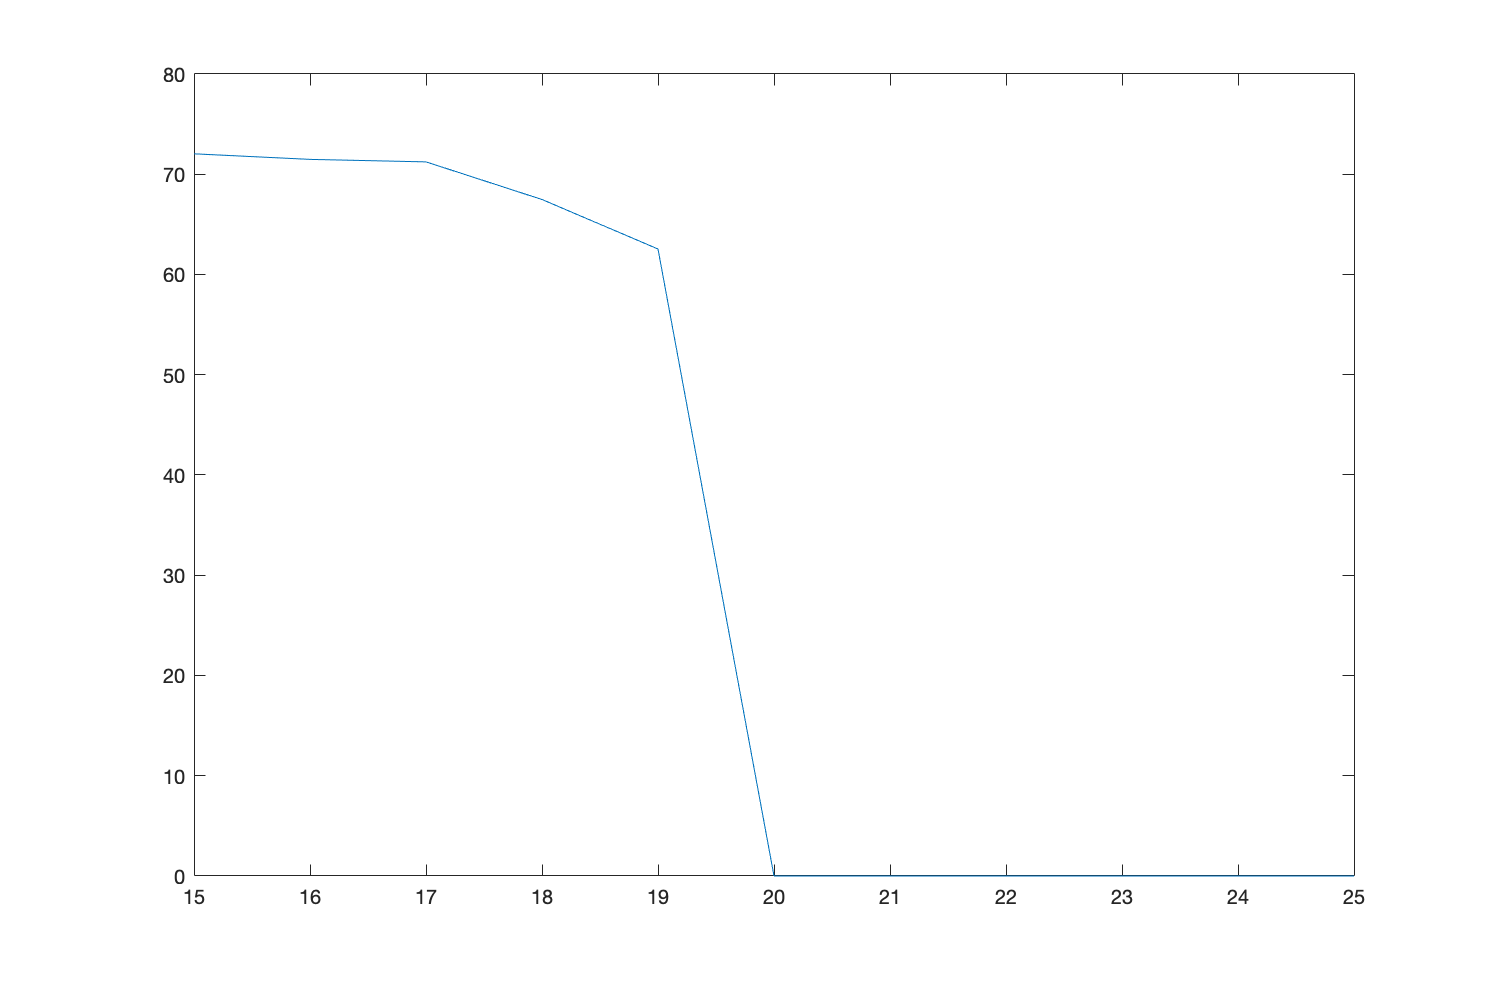

j =1;
for i=15:25
    [U,S,V] = rand_svd(A,i);
    err(j) = norm(A - U*S*V');
    j = j+1;
end
plot(15:25,err)

## N-body Problem

Let us try to speed up the matrix-vector product $$Aq = \phi$$ whichis defined by,


$$$$\phi_i = \sum_{j=1}^{N}{\sin(k(r_i-r_j))}\times q_j$$$$


The Naive Implementation

N = 5000;
%k=0.5;
x_charges = linspace(0,1,N);
q_charges = randn(N,1);
A = sin(get_fullmatrix(x_charges));
tic
phi_original = A * q_charges;
toc

Elapsed time is 0.043668 seconds.


The fast method to evaluate $$\phi$$ by decomposing into two terms


$$$$\phi_i = \sum_{j=1}^{N}{(\sin(kr_i)*\cos(kr_j)- \cos(kr_i)*\sin(kr_j))}\times q_j$$$$



$$$$a = \sum_{j=1}^{N}\cos(kr_j)\times q_j$$$$



$$$$b = \sum_{j=1}^{N}\sin(kr_j)\times q_j$$$$



$$$$\phi_i = a*\sin(kr_i)-b*\cos(kr_i)$$$$


u = sin(x_charges)';
v = cos(x_charges)';
B = u*v' - v*u';
tic
a = (v'*q_charges);
b = (u'*q_charges);
phi_fast = a*u - b*v;
toc

Elapsed time is 0.033094 seconds.



norm(phi_original-phi_fast)

ans = 2.9754e-12

## Interpolation as a low-rank approximation

Consider two non overlapping domains as [a,b] [c,d], the points in the domain are denoted as X,Y respectively and X_r Y_r represents the sample points in that domain, 

Then the matrix K(X,Y) can be represented using 


$$$$K(X,Y) = \mathcal{L}(X,X_r)K(X_r,Y_r)\mathcal{L}(Y_r,Y)$$$$


where $\mathcal{L}$ is legrange interpolation operator